clc; clear; close all;


## Load Pressure-Time Data

load('E2038.mat'); % Ensure p contains multi-column pressure data

% Mean-subtraction to remove DC offset (adjust column selection)
data = (p(:,3) - mean(p(1:100,3))) * 1000; % Pressure [mbar]
Fs = fs;  % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;


## Perform Empirical Wavelet Transform (EWT)


MaxNumPeaks = 5; % Set max number of peaks for adaptive segmentation
[mra, cfs, wfb, info] = ewt(data, 'MaxNumPeaks', MaxNumPeaks);


## Extract Peak Frequencies and Passbands


PeakFrequencies = Fs * info.PeakFrequencies;
freqPassbands = Fs * info.FilterBank.Passbands;


## Determine Adaptive Cutoff Frequency (Using EWT Passbands)


% cutoffFreq = max(freqPassbands(:,2)); % Highest meaningful passband
cutoffFreq = max(PeakFrequencies); % Highest meaningful passband


## Design a Low-Pass Filter (Butterworth)

lpFilt = designfilt('lowpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency', cutoffFreq, ...
    'SampleRate', Fs);

% Wn = cutoffFreq / (Fs/2); % Normalize cutoff to Nyquist frequency
% [b,a] = butter(4, Wn, 'low'); % 4th order Butterworth filter


## Apply the Low-Pass Filter

% Zero-phase filtering
p_filtered = filtfilt(lpFilt, data);
% p_filtered = filtfilt(b, a, data);


## Compute Energy Retention


E_original = sum(abs(data).^2);
E_filtered = sum(abs(p_filtered).^2);
energy_retention = (E_filtered / E_original) * 100; % Percentage of energy retained


## Compute FFT Before and After Filtering


N = length(data);
f = linspace(0, Fs/2, N/2+1); % Frequency vector
fft_original = abs(fft(data)); fft_original = fft_original(1:N/2+1);

fft_filtered = abs(fft(p_filtered)); fft_filtered = fft_filtered(1:N/2+1);

## Plot Results

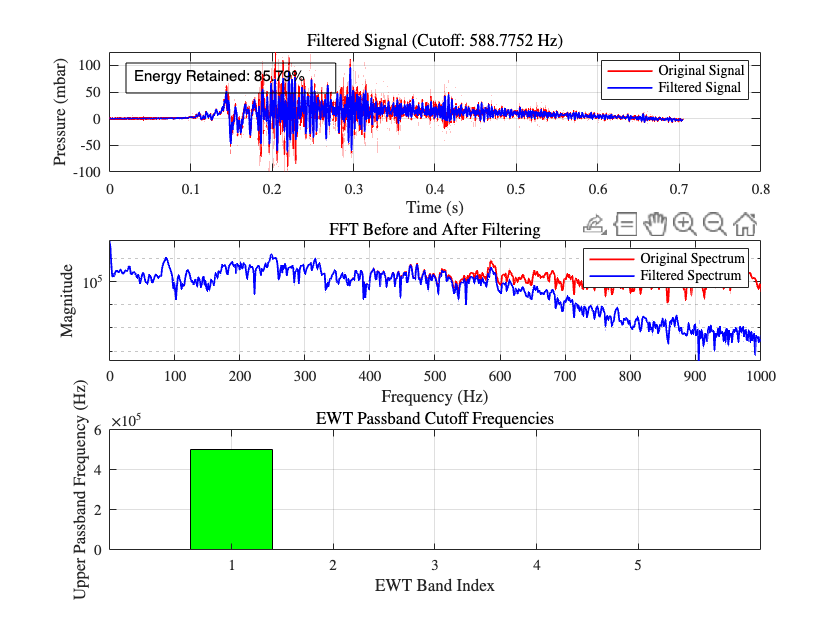


figure;

% Time Domain Plot
subplot(3,1,1);
plot(t, data, 'r', 'LineWidth', 1.2);
hold on;
plot(t, p_filtered, 'b', 'LineWidth', 1.2);
legend('Original Signal', 'Filtered Signal');
xlabel('Time (s)');
ylabel('Pressure (mbar)');
title(['Filtered Signal (Cutoff: ', num2str(cutoffFreq), ' Hz)']);
grid on;

% Energy Retention Information
annotation('textbox', [0.15, 0.8, 0.1, 0.1], 'String', ...
    sprintf('Energy Retained: %.2f%%', energy_retention), 'FitBoxToText', 'on');

% FFT Comparison
subplot(3,1,2);
semilogy(f, fft_original, 'r', 'LineWidth', 1.2); hold on;
semilogy(f, fft_filtered, 'b', 'LineWidth', 1.2);
legend('Original Spectrum', 'Filtered Spectrum');
xlabel('Frequency (Hz)');
xlim([0 1000])
ylabel('Magnitude');
title('FFT Before and After Filtering');
grid on;

% EWT Passband Cutoff Frequencies
subplot(3,1,3);
bar(1:size(freqPassbands,1), freqPassbands(:,2), 'FaceColor', 'g');
xlabel('EWT Band Index');
ylabel('Upper Passband Frequency (Hz)');
title('EWT Passband Cutoff Frequencies');
grid on;